# View Filters from GoogLeNet

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads GoogLeNet and saves the layers in a variable `ly`.

net = googlenet;
ly = net.Layers;

This code loads and displays a test image.

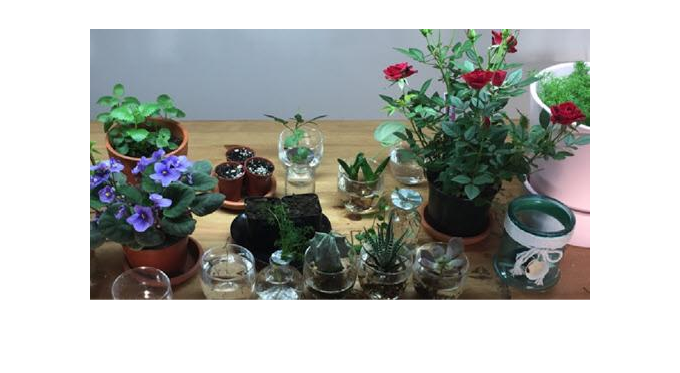

im = imread("../data/roses.jpg");
imshow(im)

## Task 1

The `Weights` property of a layer contains that layer's weights. Weights are learned during training.

Since GoogLeNet is a pretrained network, it has already learned weights that will find useful features. In this activity, you will inspect these weights in more detail.

conv = ly(2);
W = conv.Weights;

## Task 2

The weights of the first convolution layer is an array sized 7-by-7-by-3-by-64. This means that there are 64 different filters. Each of those filters is 7-by-7-by-3, so you can view them as RGB images.

These filters need to be normalized so they can be displayed correctly. The `rescale` function will scale the weights to be between 0 and 1.

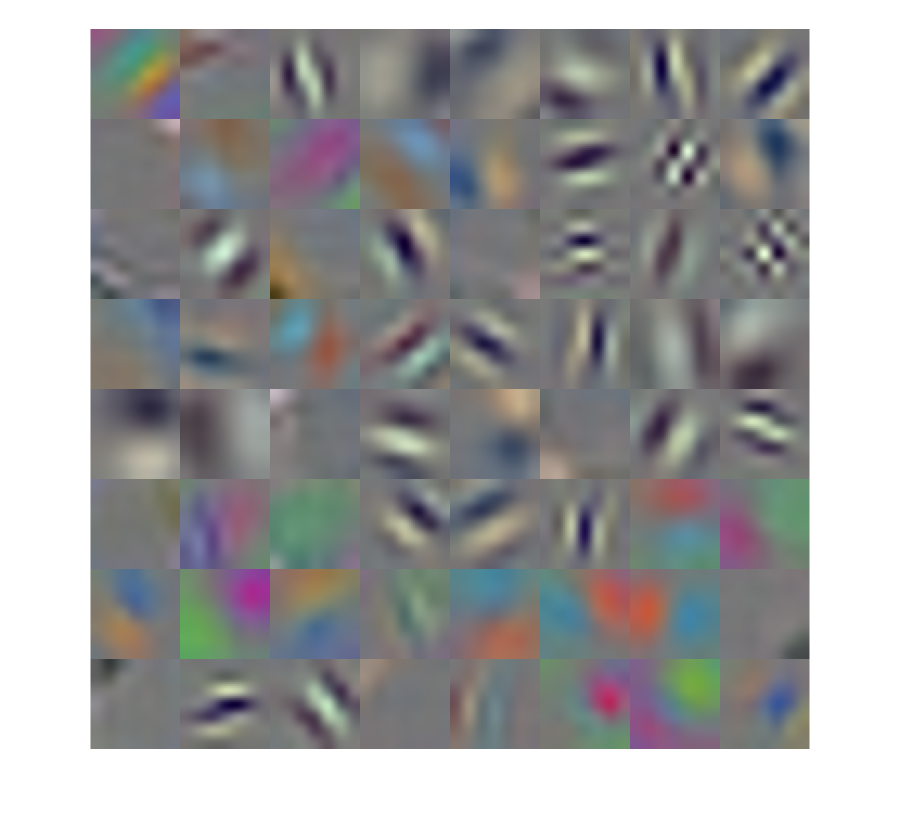

montage(rescale(W))

## Task 3

You can view a specific filter by indexing into the weights. You need all rows, columns, and RGB values of a specific filter number.

`filter` `=` `W``(``:,:,:,``n``)`

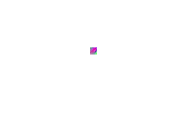

imshow(rescale(W(:, :, :, 11)))

## Task 4

The eleventh filter seems to be looking for the color pink. The image `roses.jpg` contains a few plants, but only the roses are red. This means that only the roses should be positively activated from the eleventh filter.

You can test this by getting the output of the convolution layer with the `activations` function. This function accepts three inputs: the network, the input image, and the layer to extract features from

`features` `=` `activations``(``net``,``img``,``layer``)`

actvn = activations(net, im, "conv1-7x7_s2");

## Task 5

The activations are size *m*-by-*n*-by-64. There is one activation, or feature, for every filter in the first convolution layer.

To investigate the eleventh filter, you need to get the eleventh activation channel.

`actvn``(``:,:,``n``)`

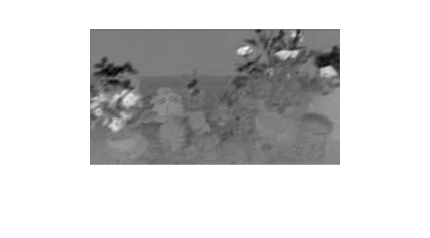

actvn11 = actvn(:, :, 11);
imshow(rescale(actvn11))